%function plotNbHeatmap(Tonal, Fz, SPL, par, proc, timeCPA, tog, timeVector)

### Plot narrowband lobing heatmap for tonals

2022-05-02 - ltrying to add all CPAs to lobing heatmap using perfectPolarPlot package merged with compareHeatmap

Double figure for each tonal showing frequency tracking and source level estimate over time

tog.VOI = 'OcEnd';
tog.tonal = 'Tonal3';
nw = 90; %number of discrete angle steps (w)
nSL = 60; %number of discrete SL steps 
addpath 'C:\Users\510PAS\PhD\Code\NW\SPL_windows'
addpath 'C:\Users\510PAS\PhD\Code\MATLAB\perfectPolarPlot'
par = setPars;
par.dBscale = 11.8;
cd(par.procPath)
files = dir(append(tog.VOI,'*.mat'));
lobData = cell(size(files));
for ii=1:length(files)
    aFileData = load(files(ii).name);
    lobData{ii} = aFileData; %.data;
end
clear ii;
%create tables that concats the SLs (tSL) and rads (tRads) from all CPAs
%input: 

tRads = []; tSL = []; levels = [];
for iFile=1:length(files)
    rads = lobData{iFile,1}.SPL.rads';
    tRads = [tRads  rads];
    if any(strcmp(tog.tonal, 'BB'))
        levels = lobData{iFile,1}.BB;   %48x743
    elseif any(strcmp(tog.tonal, 'Tonal1'))
        for ih = 1:par.nHph
            nextLevel = lobData{iFile,1}.Tonal{ih,1}(:,1)';
            levels = [levels; nextLevel];
        end
        %fullfile(append('lobData{i,1}.',tog.tonal,'.max'));  %eval   ---ok issue here is around tonal() - need to reindex after some change in way this was saved
        tSL = [tSL  levels];    %for BB we add onto
        levels = [];
    elseif any(strcmp(tog.tonal, 'Tonal2'))
        for ih = 1:par.nHph
            nextLevel = lobData{iFile,1}.Tonal{ih,2}(:,1)';
            levels = [levels; nextLevel];
        end
        tSL = [tSL  levels];    %for BB we add onto
        levels = [];
    elseif any(strcmp(tog.tonal, 'Tonal3'))
        for ih = 1:par.nHph
            nextLevel = lobData{iFile,1}.Tonal{ih,3}(:,1)';
            levels = [levels; nextLevel];
        end
        tSL = [tSL  levels];   %#ok<*AGROW> 
        levels = [];
                %stddev = smoothdata(std(lobData{i,1}.BB,0,1),'gaussian',par.smooth);
    end
%     clear levels nextLevel rads
end
% Fill outliers
tSL(tSL<30) = NaN;
%[tSL,junk] = filloutliers(tSL,"linear","percentiles",[10 90]);

%get angles
tw = rad2deg(tRads);  %provides a 1302x48 table of angles
[indw,binw] = discretize(tw,nw); %indw provides the angular index position for each SL

[indSL,binSL] = discretize(tSL,nSL);
pz = zeros(nSL+1,nw+1);    %table of source levels

for iw = 1:nw
    [pz(:,iw),~] = histcounts(tSL(indw == iw),[binSL inf], 'Normalization', 'probability');
end

pz(isnan(pz)) = 0;

clear iw;

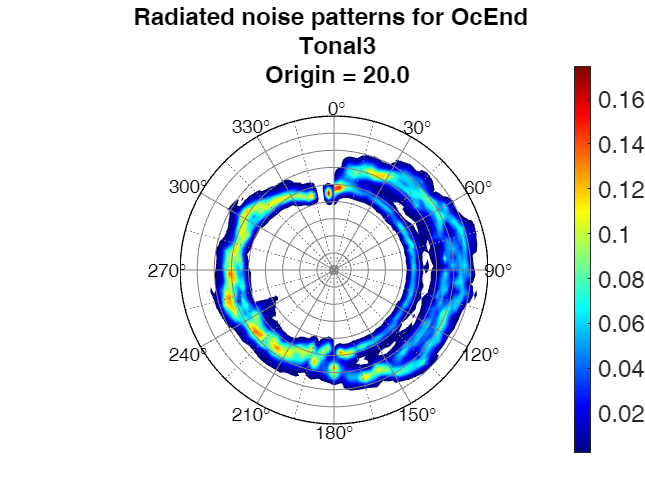


%map the data to a grid - this is where data scaling / limits are set
dirs = binw; %SPL.rads(:,iRec);
SLoffset = binSL-(min(binSL)-par.dBscale); %dBscale provides the offset from centre
[md,mf] = meshgrid(dirs, SLoffset);
rangeSL = max(max(tSL))-min(min(tSL)-par.dBscale);

%create the figure
h(1) = figure;
ph = makePolarGrid(...
    'ALabelScheme', 'normal',...
    'RTicks',        0:10:ceil(rangeSL/10)*10,...  % Radial ticks (inner circles)    'RLim',          [80 rangeSL],...
    'RUnits',        '[dB re 1\muPa]',...   % Add units to outer-most radial labels
    'RLabelScheme', 'none',...
    'RLabelFormat', '%.1f');      % Format for radial labels

% Now convert to cartesian coords
[px,py] = polgrid2cart(md, mf, ph);

% And then use contourf to plot. Optional formatting adjustments follow.
[~,hc]  = contourf(px, py, pz, 80);
uistack(hc, 'bottom');  % this will put the grid on top of the contours
hc.LevelList(1) = [];    % this removes the countours on lowest level(s)
hc.LineStyle = 'none';  % enable/disble contour lines
colormap jet

%caption = sprintf('Radiated noise patterns for %s \n Tonal %s',tog.VOI,tog.tonal);
caption = sprintf('Radiated noise patterns for %s \n  %s \n Origin = %.1f',tog.VOI,tog.tonal,(min(min(tSL))-par.dBscale));
title(caption, 'FontSize', par.fontSize);
colorbar('Location','manual','fontsize',par.fontSize,'Position', [0.89 0.098 0.026 0.77])

saveas(h(1), fullfile(par.figPath,append(tog.VOI,'_', tog.tonal, '_rnlHeatmap.tif')));

saveas(h(1), fullfile(par.figPath,append(tog.VOI,'_', tog.tonal, '_rnlHeatmap')));

## Cutting floor

% SLoffset = binSL-min(binSL); %Tonal{iRec,iTonal}(:,1)
% [md,mf] = meshgrid(dirs, SLoffset);
% %BDmatrixq = interp2(xrow,ycol,BDmatrix,md,mf,'cubic');
% rangeSL = max(max(tSL))-min(min(tSL)-par.dBscale);
% % [md,mf] = meshgrid(rad2deg(SPL.rads(:,iRec)),Tonal{iRec,iTonal}(:,1));

%RTicks --- round(floor(min(min(tSL))),-1):10:ceil(max(max(tSL))),...  % Source Level (dB) ticks (inner circles)


% dirs = binw; %SPL.rads(:,iRec);
% SLoffset = binSL-(min(binSL)-par.dBscale); %dBscale provides the offset from centre
% [md,mf] = meshgrid(dirs, SLoffset);
% rangeSL = max(max(tSL))-min(min(tSL)-par.dBscale);